# Danion and Flanagan 2018 - Different gaze strategies during eye versus hand tracking of a moving target

Created April 26, 2021

clear; clc;
% cd('/Users/duncan/OneDrive - University of Delaware - o365/Documents/Presentations/Danion_Flanagan_18')

## Target motion

Combination of two sinusoids along both x and y dimensions.


$$x_t =A_{1x} \;\cos \;\omega t+A_{2x} \;\cos \left(h_x \omega \;t-\varphi {\;}_x \right)$$



$$y_t =A_{1y} \;\cos \;\omega t+A_{2y} \;\cos \left(h_y \omega \;t-\varphi {\;}_y \right)$$


% annomyous function 
combSins = @(x) x(1) * cosd(x(2)*x(3)) + x(4) * cosd(x(5) * x(2) * x(3) - x(6)); % [A1, omega, t, A2, h, phi]

% ICs
A1x = [5,4,4,5,5.1]; % cm 
A2x = [5,5,5.1,5,5.2]; % cm 
Hx = [2,2,3,3,2]; % harmonic x 
Px = [45, -60, -60, 90, -90]; % Phase x 
A1y = [5,3,4,3.4,4]; % cm
A2y = [5,5,5.2,5,5]; % cm 
Hy = [3,3,2,2,3]; % harmonic y 
Py = [-135, -135, -135, 45, 22.5]; % Phase y 
time = 1:1:10000; % time 
omega = 0.073; % Hz (fundamental)
% guestimated results  'experiment_outcome_stat'
ET_et_cm_mu = 1;
ET_et_cm_sigma = 0.2; 
HT_et_cm_mu = 0.98;
HT_et_cm_sigma = 0.1;
ET_et_ms_mu = 26;
ET_et_ms_sigma = 2;
HT_et_ms_mu = 35;
HT_et_ms_sigma = 2;
ET_sps = 2.76; % saccade per second
HT_sps = 2.06; 
hand_cm_mu = 0;
hand_cm_sigma = 0.4;
hand_ms_mu = 108;
hand_ms_sigma = 8; 
new_hand_noise = false; 
ii = 0; 

xt = nan([length(time), length(Py)]);
yt = nan([length(time), length(Py)]);
xy = nan([length(time), length(Py), 2, 3]); % time, trajectory number, xy, trajectory/eye/hand
% Calculate
filenames = strings([length(Py), 1]); 
for i = 1:length(Py) % number of trajectories 
    filenames{i} = sprintf('trajectory%d', i); 
    for t = 1:length(time) 
        xt(t,i) = combSins([A1x(i), omega, t, A2x(i), Hx(i), Px(i)]);
        yt(t,i) = combSins([A1y(i), omega, t, A2y(i), Hy(i), Py(i)]);
        xy(t,i,:,1) = rotateByDeg(xt(t,i), yt(t,i), 60); % rotate to be more accurate to paper 
        if t <= ET_et_ms_mu+5  % starting off 
            eye_delay = 0;
            eye_noise = 0;
        else 
            eye_delay = ET_et_ms_mu; 
            if rem(t,150) == 0 % new noise 
                eye_noise = normrnd(0,0.3); 
            elseif rem(t,ET_sps) < 0.01 % catch up saccade 
                eye_noise = 0; 
            end
        end
        if t <= hand_ms_mu +5 % starting off 
            hand_delay = 0;
            hand_noise = 0;
        else
            hand_delay = hand_ms_mu;
            if rem(t,700) == 0 % new noise 
                hand_noise_total = linspace(0, normrnd(0,0.4), 150);
                new_hand_noise = true;
                ii = 1; 
            end
            if ii == 150
                new_hand_noise = false;
            elseif new_hand_noise 
                hand_noise = hand_noise_total(ii);
                ii = ii+1;
            end
        end
        xy(t,i,:,2) = xy(t-eye_delay,i,:,1) + eye_noise; % eye
        xy(t,i,:,3) = xy(t-hand_delay,i,:,1) + hand_noise; % hand
    end
end

## Figure 4

Replicate figure 4 to test if shapes are right 

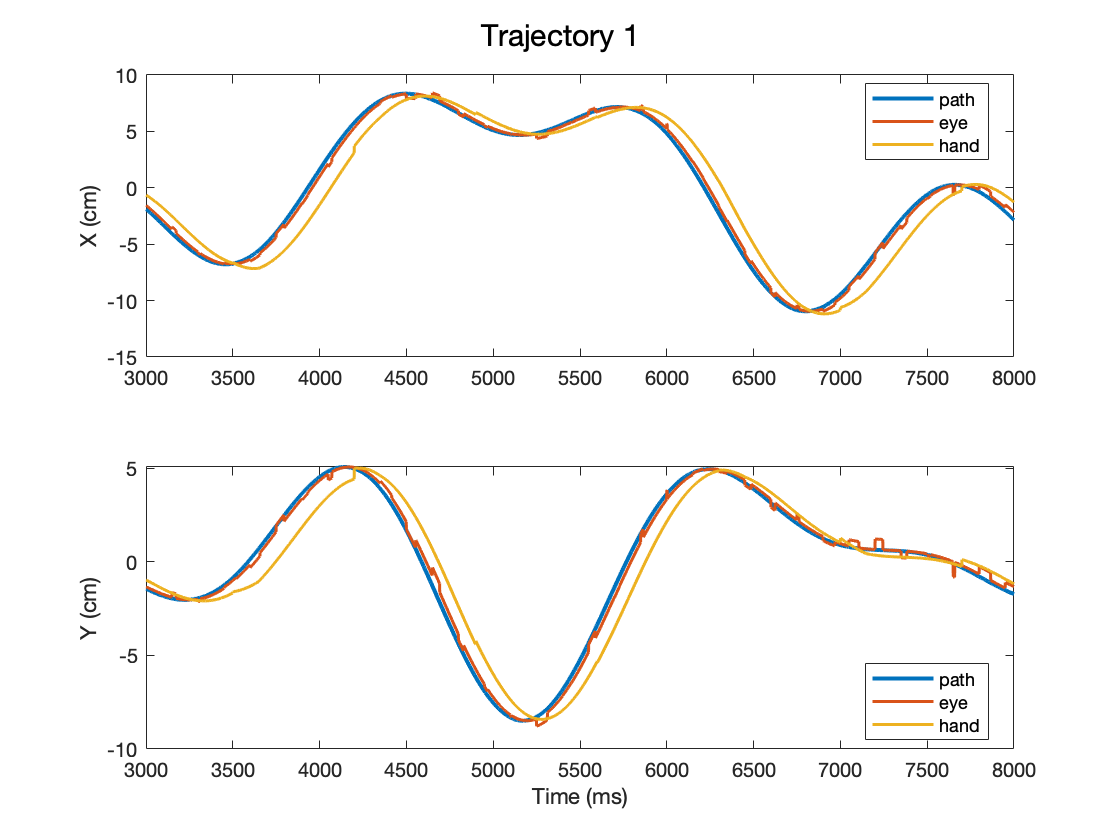

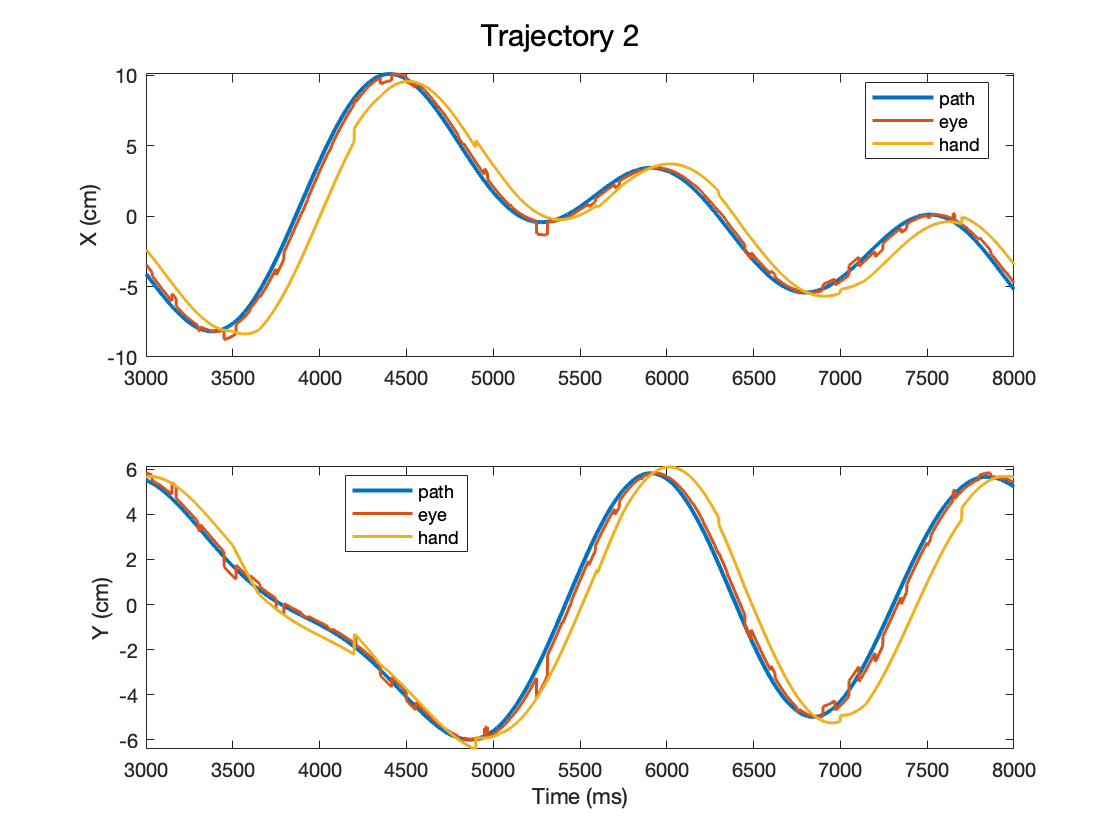

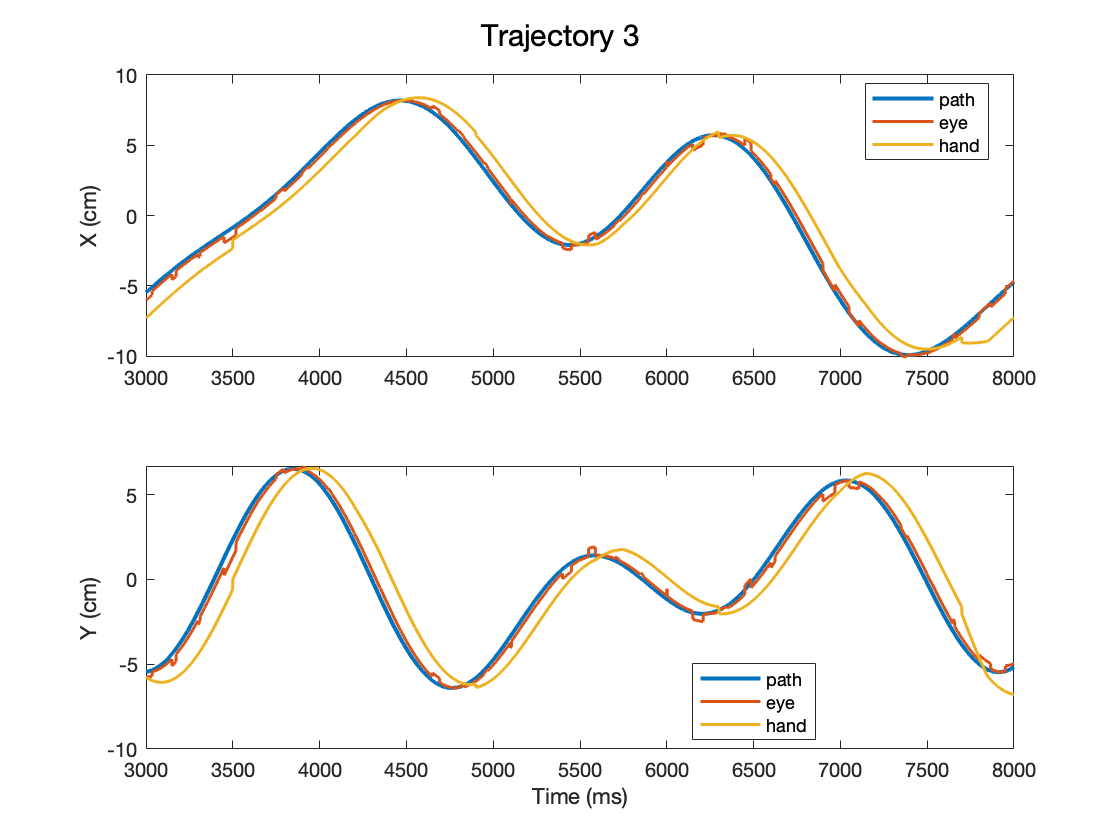

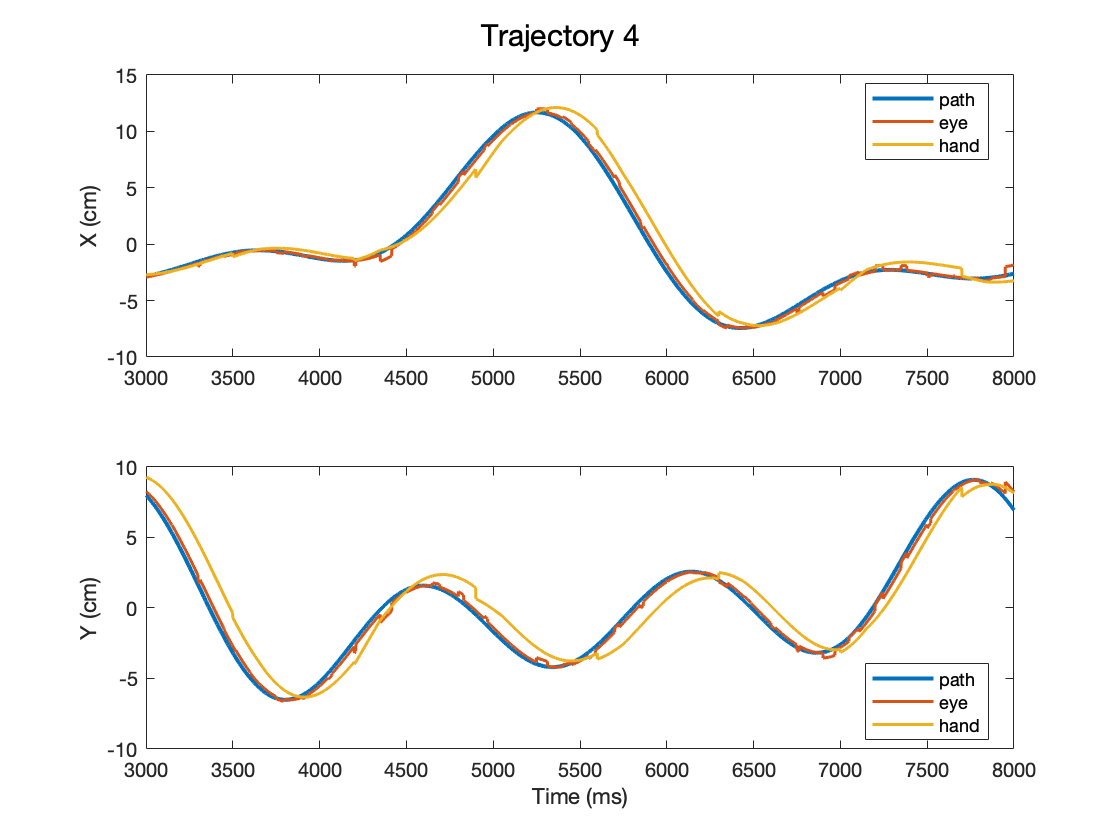

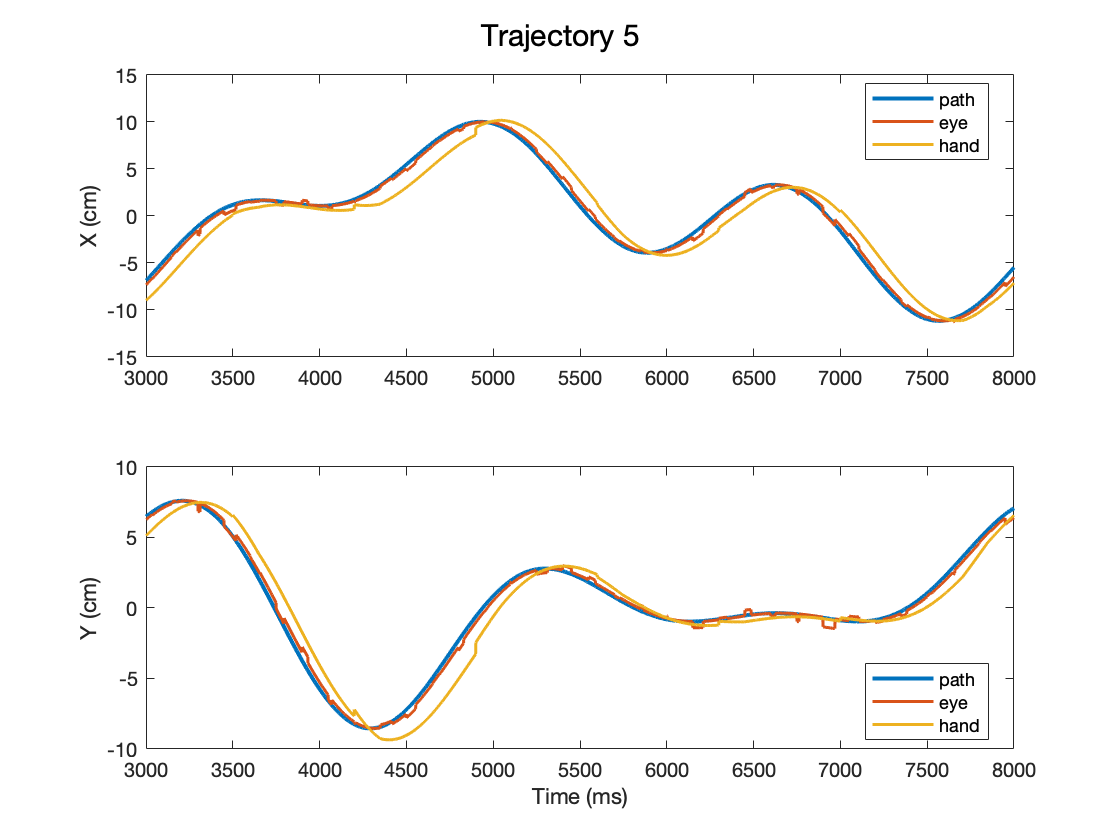

% IC
log_idx = time>3000 & time <= 8000; 
% each trajectory 
for i = 1:length(Py)
    figure;
    subplot(2,1,1);
    plot(time(log_idx), xy(log_idx,i,1,1), 'linewidth', 2); % trajectory 
    hold on 
    plot(time(log_idx), xy(log_idx,i,1,2), 'linewidth', 1.5); % eye 
    plot(time(log_idx), xy(log_idx,i,1,3), 'linewidth', 1.5); % hand 
    legend('path', 'eye', 'hand', 'location', 'best')
    ylabel('X (cm)')
    subplot(2,1,2);
    plot(time(log_idx), xy(log_idx,i,2,1), 'linewidth', 2); % trajectory 
    hold on 
    plot(time(log_idx), xy(log_idx,i,2,2), 'linewidth', 1.5); % eye 
    plot(time(log_idx), xy(log_idx,i,2,3), 'linewidth', 1.5); % hand 
    legend('path', 'eye', 'hand', 'location', 'best')
    ylabel('Y (cm)')
    sgtitle(sprintf('Trajectory %d', i))
%     SP_labels('x', 'Time (ms)')
end

## Behavior

% visualize 
for i = 1:length(Py)  
    for type = 1:2
        if type == 1
            exp = 'eye-track';
        elseif type == 2
            exp = 'hand-track';
        end
        figure;
        plot(xy(:,i,1,1), xy(:,i,2,1), '-', 'linewidth', 2, 'color', [.75 .75 .75]); % trajectory 
        hold on 
        dot = plot(xy(1,i,1,1), xy(1,i,2,1), 'mo', 'markersize', 10, 'markerfacec', 'm'); % target 
        eye = plot(xy(1,i,1,2), xy(1,i,2,2), 'g+', 'markersize', 7, 'markerfacec', 'g', 'linewidth', 2); % eye 
        if type == 2
            hand = plot(xy(1,i,1,3), xy(1,i,2,3), 'ro', 'markersize', 7, 'markerfacec', 'r', 'linewidth', 2); % hand 
        end
        xlabel('x (cm)'); ylabel('y (cm)');
        title(sprintf('Trajectory %d', i))
        set(gcf, 'visible', 'on');
        axis manual 
%         kBackground(gca);
        
%         writeGif(append(filenames{i}, '_', exp, '.gif'), 1, 0.001)
        
        for t = 2:60:10000 % 2:length(time)
            set(dot, 'XData', xy(t,i,1,1));
            set(dot, 'YData', xy(t,i,2,1));
            set(eye, 'XData', xy(t,i,1,2));
            set(eye, 'YData', xy(t,i,2,2));
            if type == 2
                set(hand, 'XData', xy(t,i,1,3));
                set(hand, 'YData', xy(t,i,2,3));
            end
            pause(0.001)
%             writeGif(append(filenames{i}, '_', exp, '.gif'), t, 0.001)
        end
        close(gcf)
    end
end

function xy = rotateByDeg(x,y,deg)
rotationMatrix = [cosd(deg), sind(deg); -sind(deg), cosd(deg)];
xy = rotationMatrix * [x;y];
end